# Autoencoders for Wireless Communications

k = 8;    % number of input bits
M = 2^k;  % number of possible input symbols
n = 4;    % number of channel uses
rng(42);

% Feature Extractor
feLayers = [
    fullyConnectedLayer(256, 'Name', 'fe_initial')
    reluLayer("Name","relu_f1")
    fullyConnectedLayer(8, 'Name', 'feature_extractor')
];
% Phase Estimator
peLayers = [
    fullyConnectedLayer(256, 'Name', 'pe_initial')
    reluLayer("Name","relu_p1")
    fullyConnectedLayer(128, 'Name', 'phase_estimator_dense1')
    reluLayer("Name","relu_p2")
    fullyConnectedLayer(2, 'Name', 'phase_estimator')
    pe_2Layer("Name","pe_2")
];

% Offset Estimator
oeLayers = [
    fullyConnectedLayer(256, 'Name', 'oe_initial')
    reluLayer("Name","relu_o1")
    fullyConnectedLayer(128, 'Name', 'oe_dense1')
    reluLayer("Name","relu_o2")
    fullyConnectedLayer(32, 'Name', 'oe_dense2')
    reluLayer("Name","relu_o3")
    fullyConnectedLayer(16, 'Name', 'offset_estimator')
    softmaxLayer("Name","softmax_oe")
];

SDLayer_ = [SDLayer("Name","SD_mini_Layer")];
SDLayerGraph = layerGraph(SDLayer_);

% Define the input layer 
inputLayer = sequenceInputLayer(1, 'Name', 'Input', 'Normalization', 'none'); 
% Define the initial layers 
initialLayers = [ 
    inputLayer
    embeddingLayer2(M,M,"Name","embeddingLayer")
    %fullyConnectedLayer(256, 'Name', 'Embedding') 
    reshapeLayer(1, 256, 'Name', 'reshape_1') 
    convolution1dLayer(1, 256, 'Name', 'Conv1D_1') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 128, 'Name', 'Conv1D_2') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 64, 'Name', 'Conv1D_3') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 2 * n, 'Name', 'Conv1D_4') 
    layerNormalizationLayer
    helperAEWNormalizationLayer("Method", "Energy", "Name", "Normalization") 
    SlidingWindow(13, "Name", "SlidingWindow") 
    StochasticChannelv3('Name', 'StochasticChannelv3') 
    helperCustomizeNoiseLayer('Name', 'NoiseLayer')
    connectionLayer ];

% Define the remaining layers 
remainingLayers = [ 
    reshapeLayer(1, 58, 'Name', 'reshape_2')
    %layerNormalizationLayer('Name', 'layer_norm')
    convolution1dLayer(1, 64, 'Name', 'Conv1D_Dec1') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 128, 'Name', 'Conv1D_Dec2') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 256, 'Name', 'Conv1D_Dec3') 
    eluLayer 
    %layerNormalizationLayer
    reshapeLayer2("Name","OutputReshaper")
    fullyConnectedLayer(M, 'Name', 'Output') 
    softmaxLayer('Name', 'Softmax') 
    classificationLayer("Name", "classoutput") ];



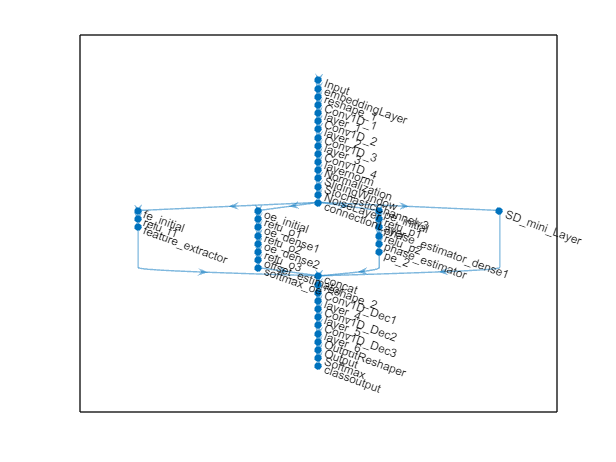

lgraph = layerGraph();

% Add initial layers 
lgraph = addLayers(lgraph, initialLayers); 

% Concatenate the outputs from the submodels 
concatLayer = concatenationLayer(1, 4, 'Name', 'concat'); 
% Add submodels 

lgraph = addLayers(lgraph, feLayers); 
lgraph = addLayers(lgraph, peLayers); 
lgraph = addLayers(lgraph, oeLayers);
lgraph = addLayers(lgraph, SDLayer_);
lgraph = addLayers(lgraph, concatLayer);


% Add remaining layers 
lgraph = addLayers(lgraph, remainingLayers); 

% Connect the layers 
lgraph = connectLayers(lgraph, 'connectionLayer', 'fe_initial'); 
lgraph = connectLayers(lgraph, 'connectionLayer', 'pe_initial'); 
lgraph = connectLayers(lgraph, 'connectionLayer', 'oe_initial'); 
lgraph = connectLayers(lgraph, 'connectionLayer', 'SD_mini_Layer'); 




lgraph = connectLayers(lgraph, 'SD_mini_Layer', 'concat/in1'); 
lgraph = connectLayers(lgraph, 'pe_2', 'concat/in2'); 
lgraph = connectLayers(lgraph, 'feature_extractor', 'concat/in3'); 
lgraph = connectLayers(lgraph, 'softmax_oe', 'concat/in4'); 
% Connect the concatenated output to the Conv1D_Dec1 layer 
lgraph = connectLayers(lgraph, 'concat', 'reshape_2'); 
plot(lgraph)

% Create input data for 100 sequences, each with a single time step
numSequences = 9600;
% Define categories (assuming 0-255 are the possible categories)
categories = 0:255;

% Create training data for 6400 sequences
inputTData = cell(1, numSequences);
TL = cell(1, numSequences);  % Cell array for training labels

for i = 1:numSequences
    % Each sequence is a single value (1 time step, 1 feature)
    inputTData{i} = randi([0, 255], 1, 1);  % Random integer between 0-255
    % Convert to categorical label (since it's a sequence-to-sequence task, use a sequence of categories)
    TL{i} = categorical(inputTData{i}, categories);  % Single categorical value per sequence
end

numSequences = 6400;
% Create validation data (same structure as training data)
inputVData = cell(1, numSequences);
VL = cell(1, numSequences);  % Cell array for validation labels

for i = 1:numSequences
    % Each sequence is a single value (1 time step, 1 feature)
    inputVData{i} = randi([0, 255], 1, 1);  % Random integer between 0-255
    % Convert to categorical label for validation
    VL{i} = categorical(inputVData{i}, categories);  % Single categorical value per sequence
end

numSequences = 3200;
% Create validation data (same structure as training data)
inputTEData = cell(1, numSequences);
TEL = cell(1, numSequences);  % Cell array for validation labels

for i = 1:numSequences
    % Each sequence is a single value (1 time step, 1 feature)
    inputTEData{i} = randi([0, 255], 1, 1);  % Random integer between 0-255
    % Convert to categorical label for validation
    TEL{i} = categorical(inputTEData{i}, categories);  % Single categorical value per sequence
end

display(inputTData)

inputTData = 1×9600 cell array
  Columns 1 through 946

    {[96]}    {[149]}    {[128]}    {[168]}    {[71]}    {[30]}    {[20]}    {[49]}    {[123]}    {[60]}    {[111]}    {[7]}    {[160]}    {[224]}    {[12]}    {[55]}    {[81]}    {[73]}    {[10]}    {[27]}    {[233]}    {[182]}    {[245]}    {[112]}    {[225]}    {[209]}    {[223]}    {[10]}    {[167]}    {[145]}    {[139]}    {[129]}    {[203]}    {[247]}    {[212]}    {[222]}    {[123]}    {[176]}    {[106]}    {[92]}    {[229]}    {[231]}    {[174]}    {[214]}    {[92]}    {[111]}    {[210]}    {[101]}    {[10]}    {[90]}    {[101]}    {[39]}    {[88]}    {[239]}    {[219]}    {[114]}    {[181]}    {[38]}    {[192]}    {[121]}    {[184]}    {[164]}    {[59]}    {[213]}    {[146]}    {[200]}    {[24]}    {[157]}    {[74]}    {[220]}    {[243]}    {[14]}    {[185]}    {[26]}    {[219]}    {[31]}    {[49]}    {[64]}    {[186]}    {[74]}    {[152]}    {[146]}    {[102]}    {[138]}    {[30]}    {[224]}    {[53]}    {[225]}    {[132

display(TL)

TL = 1×9600 cell array
  Columns 1 through 946

    {[96]}    {[149]}    {[128]}    {[168]}    {[71]}    {[30]}    {[20]}    {[49]}    {[123]}    {[60]}    {[111]}    {[7]}    {[160]}    {[224]}    {[12]}    {[55]}    {[81]}    {[73]}    {[10]}    {[27]}    {[233]}    {[182]}    {[245]}    {[112]}    {[225]}    {[209]}    {[223]}    {[10]}    {[167]}    {[145]}    {[139]}    {[129]}    {[203]}    {[247]}    {[212]}    {[222]}    {[123]}    {[176]}    {[106]}    {[92]}    {[229]}    {[231]}    {[174]}    {[214]}    {[92]}    {[111]}    {[210]}    {[101]}    {[10]}    {[90]}    {[101]}    {[39]}    {[88]}    {[239]}    {[219]}    {[114]}    {[181]}    {[38]}    {[192]}    {[121]}    {[184]}    {[164]}    {[59]}    {[213]}    {[146]}    {[200]}    {[24]}    {[157]}    {[74]}    {[220]}    {[243]}    {[14]}    {[185]}    {[26]}    {[219]}    {[31]}    {[49]}    {[64]}    {[186]}    {[74]}    {[152]}    {[146]}    {[102]}    {[138]}    {[30]}    {[224]}    {[53]}    {[225]}    {[132]}    {[

% Training options

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.0003, ...
    'SquaredGradientDecayFactor', 0.999, ...
    'GradientDecayFactor', 0.9, ... 
    'Epsilon', 1e-07, ... 
    "GradientThreshold",1, ...
    'MaxEpochs', 100, ...
    "SequenceLength","longest", ...
    'MiniBatchSize', 32, ...
    'LearnRateSchedule', 'piecewise', ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {inputVData, VL}, ...
    'ValidationPatience', 20, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |        0.00% |        0.56% |       5.5464 |       5.5444 |          0.0003 |
|       1 |          50 |       00:00:16 |        0.00% |        1.17% |       5.5501 |       5.5217 |          0.0003 |
|       1 |         100 |       00:00:24 |        3.12% |        1.56% |       5.4535 |       5.4024 |          0.0003 |
|       1 |         150 |       00:00:32 |        0.00% |        1.34% |       5.5483 |       5.0848 |          0.0003 |
|       

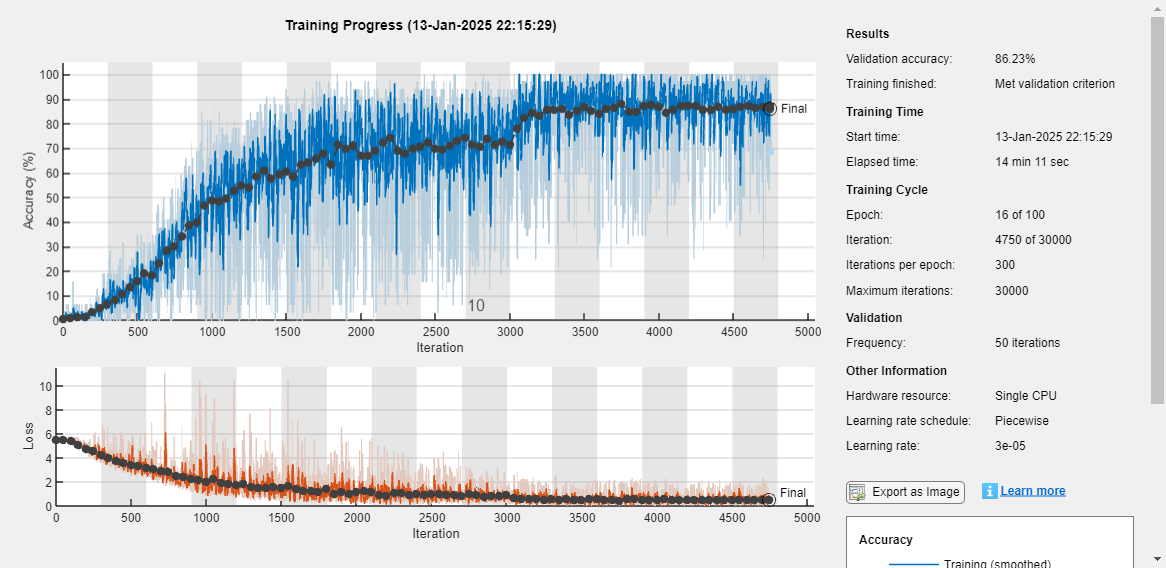

% Train the autoencoder
net = trainNetwork(inputTData, TL, lgraph, options);

predictions = predict(net, inputTEData);
display(TEL)

TEL = 1×3200 cell array
  Columns 1 through 946

    {[142]}    {[52]}    {[105]}    {[44]}    {[170]}    {[145]}    {[160]}    {[247]}    {[102]}    {[55]}    {[255]}    {[14]}    {[207]}    {[41]}    {[170]}    {[121]}    {[214]}    {[187]}    {[44]}    {[170]}    {[55]}    {[43]}    {[21]}    {[29]}    {[180]}    {[253]}    {[173]}    {[181]}    {[200]}    {[227]}    {[68]}    {[154]}    {[55]}    {[134]}    {[53]}    {[16]}    {[22]}    {[249]}    {[1]}    {[176]}    {[227]}    {[100]}    {[181]}    {[89]}    {[135]}    {[239]}    {[10]}    {[68]}    {[27]}    {[126]}    {[197]}    {[250]}    {[39]}    {[11]}    {[35]}    {[248]}    {[81]}    {[68]}    {[188]}    {[30]}    {[89]}    {[37]}    {[249]}    {[72]}    {[68]}    {[162]}    {[4]}    {[167]}    {[116]}    {[47]}    {[124]}    {[255]}    {[214]}    {[249]}    {[237]}    {[210]}    {[85]}    {[186]}    {[100]}    {[109]}    {[223]}    {[52]}    {[75]}    {[238]}    {[179]}    {[16]}    {[31]}    {[148]}    {[204]}    {[202]}

display(predictions)

predictions = 3200×1 cell array
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}


YPred = classify(net,inputTEData, ...
    MiniBatchSize=1024, ...
    SequenceLength="longest");
display(YPred)

YPred = 3200×1 cell array
    {[142]}
    {[52 ]}
    {[105]}
    {[44 ]}
    {[170]}
    {[145]}
    {[160]}
    {[247]}
    {[102]}
    {[55 ]}
    {[255]}
    {[14 ]}
    {[207]}
    {[41 ]}
    {[170]}
    {[121]}


y = zeros(size(YPred,1),1);
t = zeros(size(YPred,1),1);
for i =1:size(YPred,1)
    y(i) = YPred{i};
    t(i) = TEL{1}{i};
end

Error using indexing
Cell contents reference from a non-cell array object.

accuracy = sum(y == t) / numel(t);
display(accuracy)
cm = confusionmat(t, y);
accuracy = sum(diag(cm)) / sum(cm(:));
display(accuracy)
plot(cm)

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |        0.00% |        0.62% |       5.5413 |       5.5447 |          0.0003 |
|       1 |          50 |       00:00:22 |        3.12% |        0.88% |       5.5356 |       5.5248 |          0.0003 |
|       1 |         100 |       00:00:30 |        0.00% |        1.34% |       5.4637 |       5.4093 |          0.0003 |
|       1 |         150 |       00:00:39 |        0.00% |        1.09% |       4.9934 |       5.1311 |          0.0003 |
|       

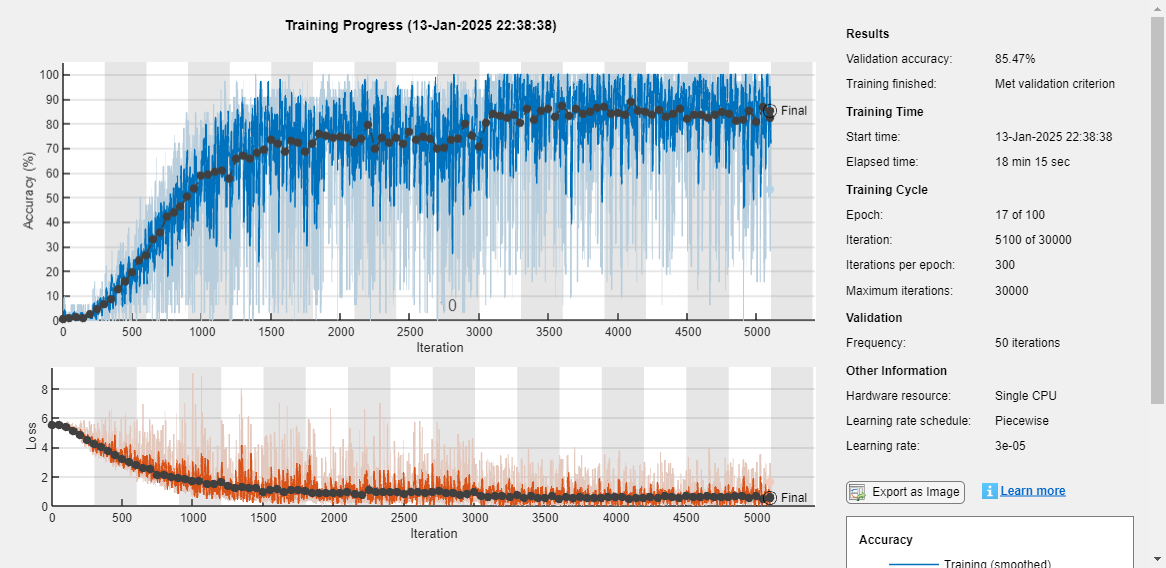

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |        0.00% |        0.36% |       5.5464 |       5.5439 |          0.0003 |
|       1 |          50 |       00:00:18 |        3.12% |        1.22% |       5.4938 |       5.5115 |          0.0003 |
|       1 |         100 |       00:00:28 |        0.00% |        1.80% |       5.2648 |       5.2978 |          0.0003 |
|       1 |         150 |       00:00:39 |        6.25% |        2.67% |       4.5705 |       4.8683 |          0.0003 |
|       

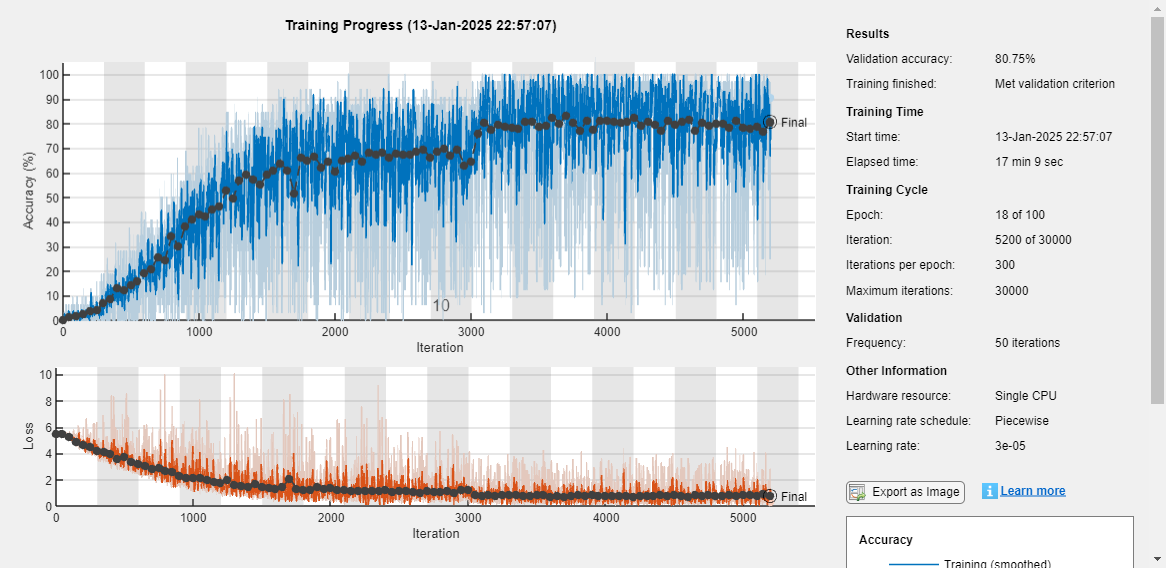

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |        0.00% |        0.38% |       5.5635 |       5.5460 |          0.0003 |
|       1 |          50 |       00:00:18 |        0.00% |        0.81% |       5.5411 |       5.5229 |          0.0003 |
|       1 |         100 |       00:00:27 |        0.00% |        2.75% |       5.2455 |       5.3667 |          0.0003 |
|       1 |         150 |       00:00:37 |        0.00% |        2.52% |       5.9484 |       4.9749 |          0.0003 |
|       

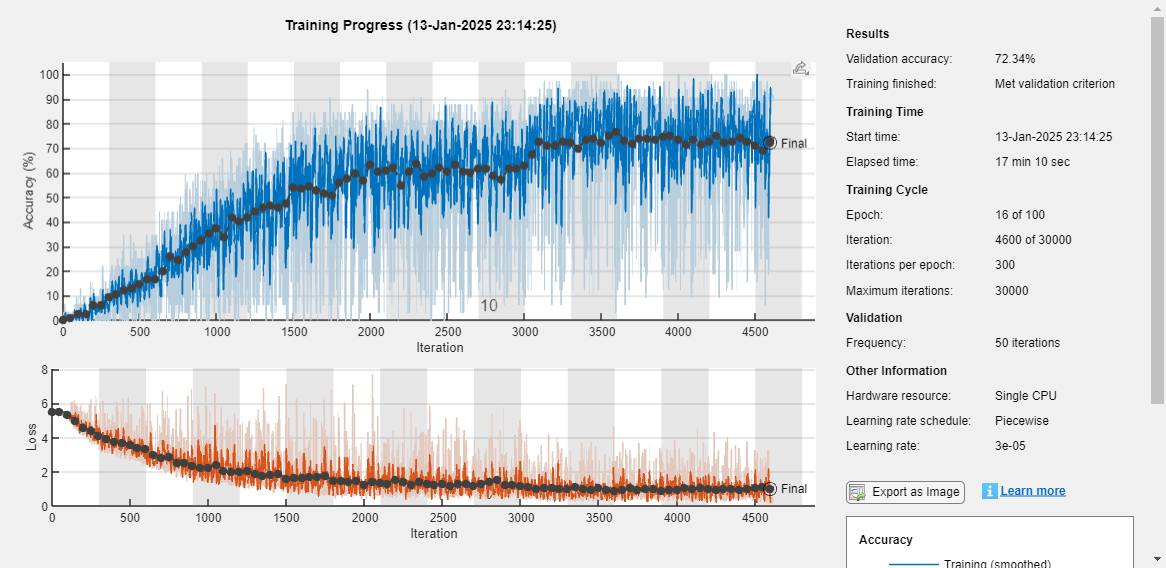

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |        0.00% |        0.48% |       5.5436 |       5.5459 |          0.0003 |
|       1 |          50 |       00:00:20 |        0.00% |        1.31% |       5.5302 |       5.5233 |          0.0003 |
|       1 |         100 |       00:00:31 |        0.00% |        1.02% |       5.4789 |       5.3689 |          0.0003 |
|       1 |         150 |       00:00:42 |        3.12% |        1.73% |       4.9285 |       5.0676 |          0.0003 |
|       

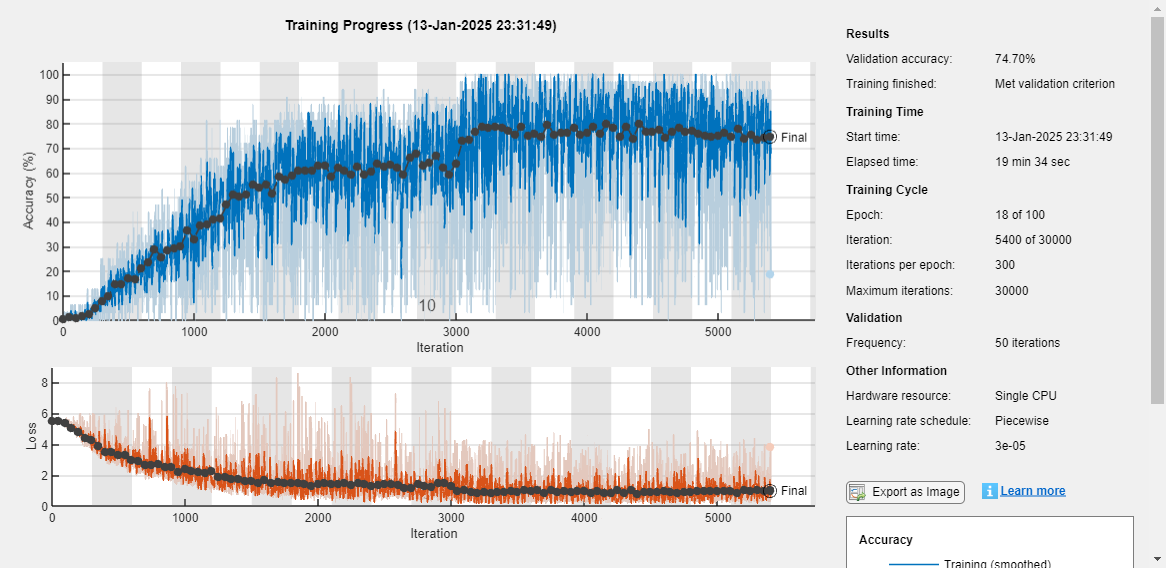

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |        0.00% |        0.52% |       5.5479 |       5.5460 |          0.0003 |
|       1 |          50 |       00:00:21 |        0.00% |        1.55% |       5.5438 |       5.5238 |          0.0003 |
|       1 |         100 |       00:00:32 |        0.00% |        1.16% |       5.2181 |       5.2819 |          0.0003 |
|       1 |         150 |       00:00:44 |        0.00% |        2.69% |       4.9089 |       5.0131 |          0.0003 |
|       

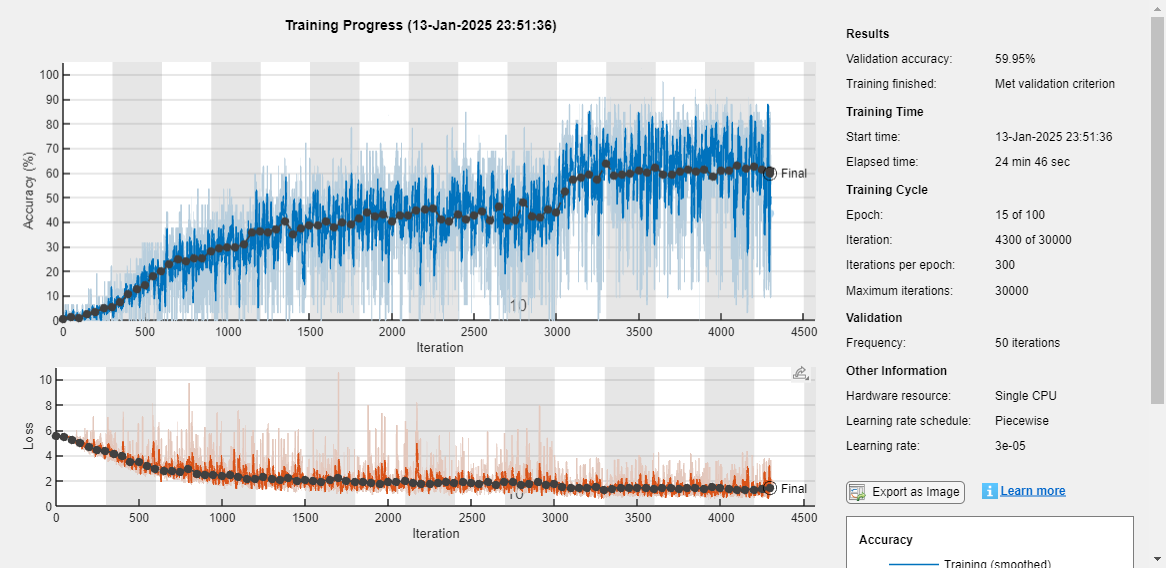

maxIter = 5;
done = false;
iterCnt = 0;
bestAccuracy = 0;
bestModel = [];
bestInfo = [];

while ~done
    % Train the autoencoder network
    [trainedNet, info] = trainNetwork(inputTData, TL, lgraph, options);
    
    % Update iteration count
    iterCnt = iterCnt + 1;
    
    % Check if the current model is the best so far
    if info.FinalValidationAccuracy > bestAccuracy
        bestAccuracy = info.FinalValidationAccuracy;
        bestModel = trainedNet;
        bestInfo = info;

    end
    
    % Check if the network converged or maximum iteration reached
    if (info.FinalValidationAccuracy > 90) || (iterCnt >= maxIter)
        done = true;
    end
end

trainedNet = bestModel;
info = bestInfo;

% Display the best accuracy
disp(['Best Accuracy: ', num2str(bestAccuracy)]);

Best Accuracy: 85.4688


predictions = predict(trainedNet, inputTEData);

YPred = classify(trainedNet,inputTEData, ...
    MiniBatchSize=1024, ...
    SequenceLength="longest");


% y = zeros(size(YPred,1),1);
% t = zeros(size(YPred,1),1);
% for i =1:size(YPred,1)
%     y(i) = YPred{i};
%     t(i) = TEL{1}{i};
% end
% accuracy = sum(y == t) / numel(t);
% display(accuracy)

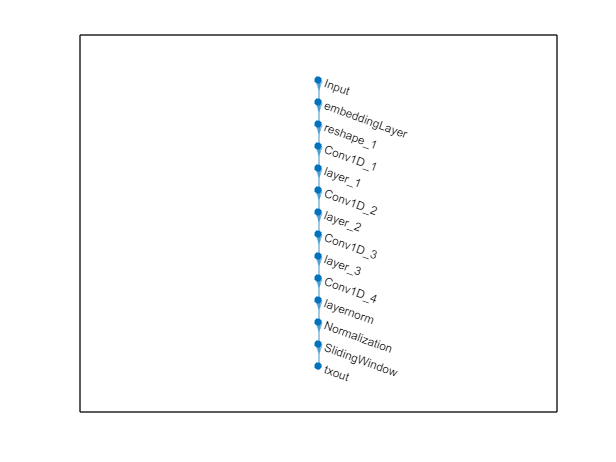

% Separate the network into encoder and decoder parts. Encoder starts with
% the input layer and ends after the normalization layer.
for idxNorm = 1:length(trainedNet.Layers)
  if isa(trainedNet.Layers(idxNorm), 'SlidingWindow')
   
    break
  end
end
lgraphTx = addLayers(layerGraph(trainedNet.Layers(1:idxNorm)), ...
  regressionLayer('Name', 'txout'));
lgraphTx = connectLayers(lgraphTx,'SlidingWindow','txout');
txNet = assembleNetwork(lgraphTx);
plot(lgraphTx);

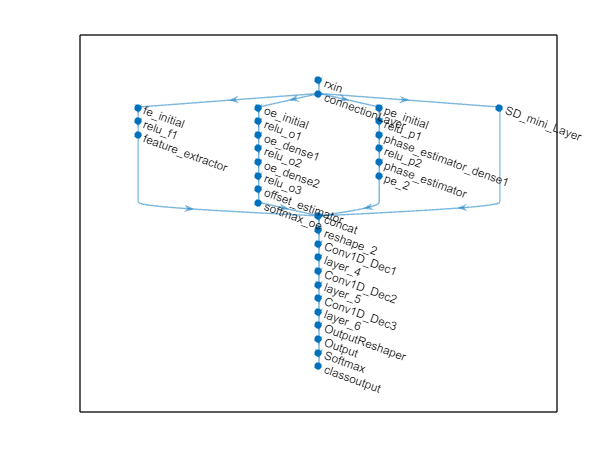


% Decoder starts after the channel layer and ends with the classification
% layer. Add a feature input layer at the beginning. 
for idxChan = idxNorm:length(trainedNet.Layers)
  if isa(trainedNet.Layers(idxChan), 'helperCustomizeNoiseLayer')
    break
  end
end

firstLayerName = trainedNet.Layers(idxChan+1).Name;
i = trainedNet.Layers(idxChan+1).InputSize;
i = 476;

lgraphRx = addLayers(layerGraph(sequenceInputLayer(i,'Name','rxin')), ...
  trainedNet.Layers(idxChan+1:16));
lgraphRx = connectLayers(lgraphRx,'rxin',firstLayerName);
lgraphRx = addLayers(lgraphRx,trainedNet.Layers(17:19));
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(16).Name,trainedNet.Layers(17).Name);
lgraphRx = addLayers(lgraphRx,trainedNet.Layers(20:25));
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(16).Name,trainedNet.Layers(20).Name);
lgraphRx = addLayers(lgraphRx,trainedNet.Layers(26:33));
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(16).Name,trainedNet.Layers(26).Name);
lgraphRx = addLayers(lgraphRx,trainedNet.Layers(34));
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(16).Name,trainedNet.Layers(34).Name);
lgraphRx = addLayers(lgraphRx,trainedNet.Layers(35:end));

lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(19).Name,[trainedNet.Layers(35).Name '/in3']);
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(25).Name,[trainedNet.Layers(35).Name '/in2']);
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(33).Name,[trainedNet.Layers(35).Name '/in4']);
lgraphRx = connectLayers(lgraphRx,trainedNet.Layers(34).Name,[trainedNet.Layers(35).Name '/in1']);
rxNet = assembleNetwork(lgraphRx);
plot(lgraphRx);

disp("activation at chanel output calculating");

activation at chanel output calculating


activationsRx = activations(trainedNet, inputTData, trainedNet.Layers(idxChan).Name);
all_receivedFeatures = activationsRx;
save('overTheAir_received_signal.mat','all_receivedFeatures');
disp("saved -- activation at chanel output");

saved -- activation at chanel output


disp("activation at chanel output calculating");

activation at chanel output calculating


activationsTx = activations(trainedNet, inputTData, trainedNet.Layers(idxNorm).Name);
all_transmittedFeatures = activationsTx;
save('overTheAir_transmitted_signal.mat','all_transmittedFeatures');
disp("saved -- activation at chanel output");

saved -- activation at chanel output
